clearvars

% Init param
M = zeros(10, 1);
for i = 1:length(M)
    M(i) = 2^i;
end

N = 2;
w = [sqrt(pi)/2, sqrt(pi)/2];
z = [-1/sqrt(2), 1/sqrt(2)];
SNR = 1.0;

rho = 0;
max_rho = 1;
delta = 0.001;
E0_values = [];  % Pel display
rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1;



% Per E0(1) - fors
E0_1 = zeros(length(M), 1);
time = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    E0_1(i) = E0(1, N, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time(i) = elapsed_time;
end
% -------------------------------------------------------------
% Per E0(1) - matrius
E0_1_matrix = zeros(length(M), 1);
time_matrix = zeros(length(M), 1);
for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    [Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);
    tic; % Time starts 
    E0_1_matrix(i) = E0_matrix(Q, pi_, G, 1);
    elapsed_time = toc; % Time ends
    time_matrix(i) = elapsed_time;
end

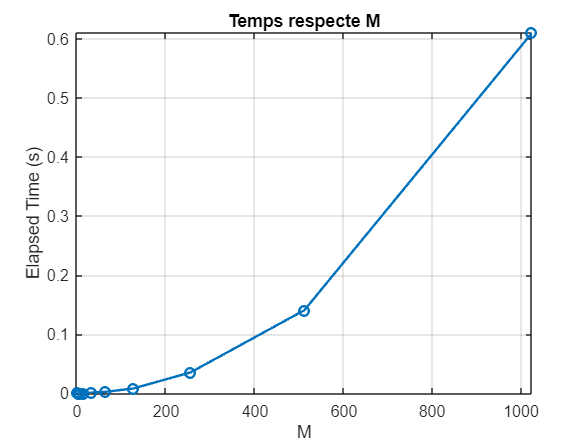

% Display
lim_y = time_matrix(length(time_matrix));
if time(length(time)) > time_matrix(length(time_matrix))
    lim_y = time(length(time));
end

% Gràfica fors
plot(M, time, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('Elapsed Time (s)'); 
title('Temps respecte M');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

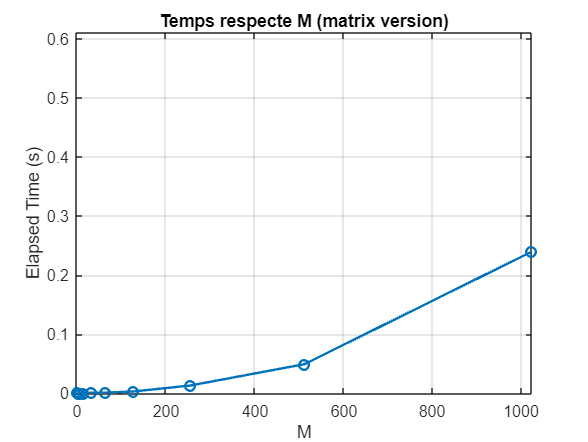



% Gràfica matrius
plot(M, time_matrix, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('Elapsed Time (s)'); 
title('Temps respecte M (matrix version)');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

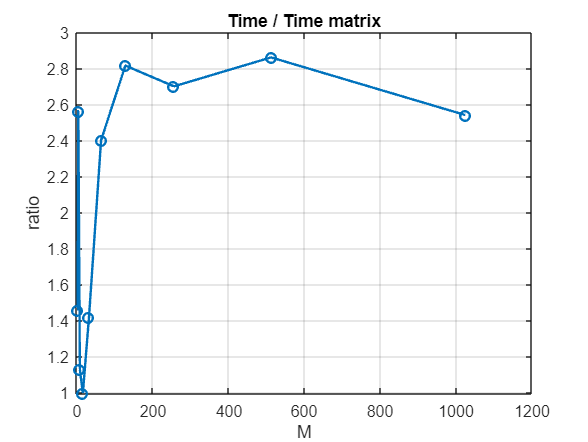

r = time./time_matrix;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time / Time matrix');

% ylim([0 lim_y]);
% xlim([0 M(length(M))]);